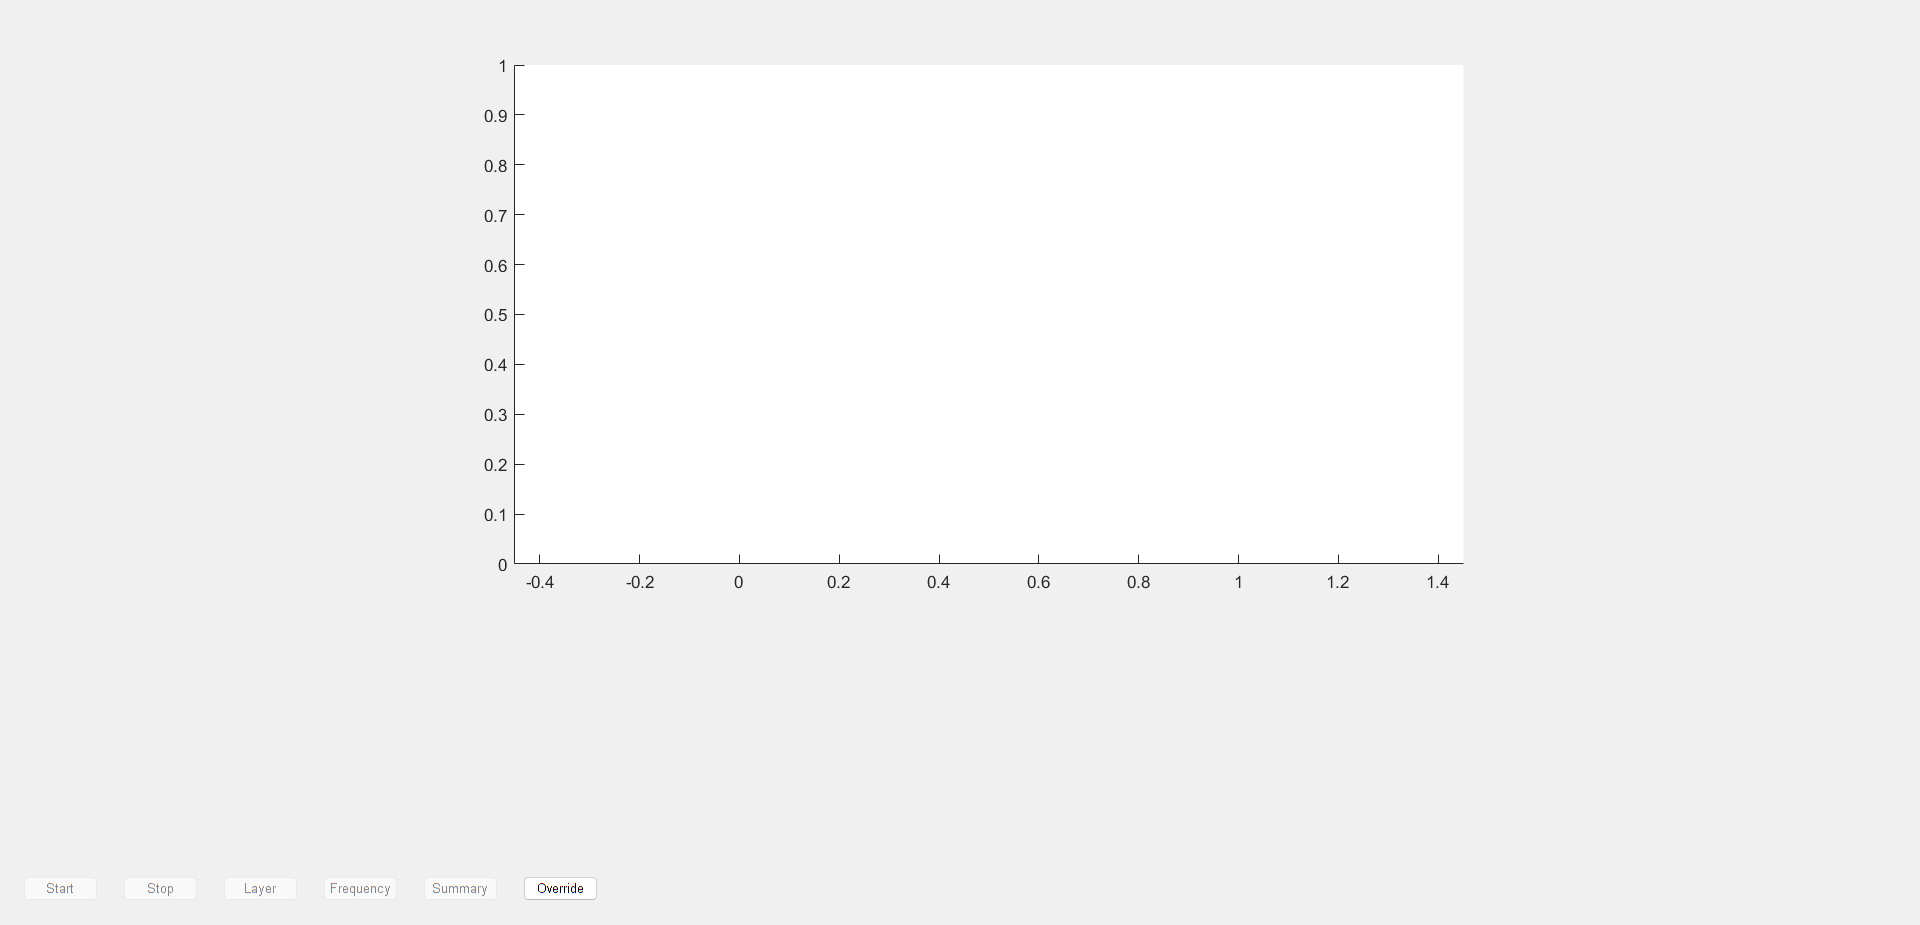

%ENGS 169 EIT Tracking Project
%Developed by Pritom Chowdhury
%EIT Tracking data, Margin Analysis, Pressure sensing and Feedback

eit_gui_matlab_file_with_margin_detection()

function eit_gui_matlab_file_with_margin_detection()
  global override;
    override = 0;

    try

     a = arduino();
       pin1 = 'A12';
        pin2 = 'D8';
        pin3 = 'D9';
        record = 0; % set to 0 to record once, set to 1 to record for time interval t
        configurePin(a,pin2,'DigitalOutput');
        configurePin(a,pin3,'DigitalOutput');
    
     % a = arduino('COM6','Mega2560');
    catch
      error('Could not connect to Arduino. Check your connection and COM port.');
    end
        % Create a figure and axes for the plot
    f = figure('Visible','off');

    ax = axes('Parent', f, 'position', [0.13 0.39  0.77 0.54]);
    axis equal

    % Create Start, Stop, Layer, Frequency, and Summary buttons
    start_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Start',...
        'Position', [20 20 60 20],...
        'Callback', @start_callback);

    stop_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Stop',...
        'Position', [100 20 60 20],...
        'Callback', @stop_callback);

    layer_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Layer',...
        'Position', [180 20 60 20],...
        'Callback', @layer_callback);

    frequency_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Frequency',...
        'Position', [260 20 60 20],...
        'Callback', @frequency_callback);

    summary_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Summary',...
        'Position', [340 20 60 20],...
        'Callback', @summary_callback);

    override_button = uicontrol('Parent', f, 'Style', 'pushbutton', 'String', 'Override',...
    'Position', [420 20 60 20],...
    'Callback', @override_callback);


    f.Visible = 'on';

    % Declare eit_data_all as a shared variable
    eit_data_all = {};

    % Declare summary_eit_data as a shared variable
    summary_eit_data = {};

    % Declare a timer for displaying the notifications
    notification_timer = timer('ExecutionMode', 'fixedRate', 'Period', 2, 'TimerFcn', @display_notification);

    function override_callback(source, event)
        %global override;
        override = 1;
     end

    function start_callback(source, event)
        folder_path = 'D:\Dartmouth_PhD\Third Semester_Mar_2023\ENGS 169\Tracking_Project\tracking_ENGS169\meat_database-20230603T063209Z-001\meat_database\2023_03_24_fat_loc1_21g'; % <--- Replace with your folder path
        mat_files = dir(fullfile(folder_path, '*.mat'));
        mat_files = sort({mat_files.name});

        % Load all EIT data
        eit_data_all = cell(0);
        for i = 1:length(mat_files)
            eit_data_all{i} = loadEITData(fullfile(folder_path, mat_files{i}));
        end

        % Start displaying EIT data
        i = 1;
        while i <= length(eit_data_all)
            plotEITDataWithMarginDetection(eit_data_all{i}, ax);
            drawnow;
            pause(1); % Pause between each file load, adjust as needed

            % Increment index
            i = i + 1;
        end
    end

    function stop_callback(source, event)
        % Clear eit_data_all
        eit_data_all = {};
    end

    function layer_callback(source, event)
        % Check if eit_data_all is empty
        if isempty(eit_data_all)
            msgbox('Please press the Start button first.', 'Error', 'error');
            return;
        end

        % Show a dialog box to choose layer
        [indx,tf] = listdlg('ListString',{'1','2','3','4'},'PromptString','Select a layer:');
        if tf
            % Filter EIT data by selected layer and display the first one
            eit_data_layer = eit_data_all(cellfun(@(x) strcmp(x.layer, num2str(indx)), eit_data_all));
            plotEITDataWithMarginDetection(eit_data_layer{1}, ax);
            drawnow;
        end
    end

   

    function frequency_callback(source, event)
        % Check if eit_data_all is empty
        if isempty(eit_data_all)
            msgbox('Please press the Start button first.', 'Error', 'error');
            return;
        end

        % Show a dialog box to choose frequency
        frequencies = cellfun(@(x) x.frequency, eit_data_all, 'UniformOutput', false);
        [indx,tf] = listdlg('ListString', frequencies, 'PromptString', 'Select a frequency:');
        if tf
            % Filter EIT data by selected frequency and display the first one
            eit_data_freq = eit_data_all(indx);
            plotEITDataWithMarginDetection(eit_data_freq{1}, ax);
            drawnow;
        end
    end

    function summary_callback(source, event)
        % Check if summary_eit_data is empty
        if isempty(summary_eit_data)
            msgbox('No tumor data available.', 'Error', 'error');
            return;
        end

        % Create a new figure for the summary EIT image
        summary_fig = figure;
        summary_ax = axes('Parent', summary_fig);
        axis equal

        % Plot the summary EIT image
        for j = 1:length(summary_eit_data)
            rectsx = summary_eit_data{j}.rectsx;
            rectsy = summary_eit_data{j}.rectsy;
            inds = summary_eit_data{j}.inds;
            sigmas_idx = summary_eit_data{j}.sigmas(inds);
            patch(summary_ax, rectsx, rectsy, 0*rectsx, sigmas_idx, 'linestyle', 'none');
            hold(summary_ax, 'on');
        end

        % Customize the plot
        colormap(summary_ax, 'jet');
        colorbar(summary_ax);
        xlabel(summary_ax, 'X');
        ylabel(summary_ax, 'Y');
        title(summary_ax, 'Summary EIT Image');

        % Display the plot
        axis tight;
        axis equal;
        hold(summary_ax, 'off');
    end

    function eit_data = loadEITData(file_path)
        mat_data = load(file_path);
        eit_data.sigmas = mat_data.sigmas;
        eit_data.pltset_xy_crp = mat_data.pltset_xy_crp;
        eit_data.mat_file = file_path;

        % Extract frequency and layer (z) from filename
        [~, filename, ~] = fileparts(file_path);
        filename_parts = split(filename, "_");

        if length(filename_parts) < 3
            warning("Unexpected filename structure. Couldn't extract frequency and layer information.");
        else
            eit_data.frequency = filename_parts{end-2};
            eit_data.layer = filename_parts{end}(2); % assuming the layer information is always like 'z1', 'z2', etc.
        end
    end

    function plotEITDataWithMarginDetection(eit_data, ax)
        sigmas = eit_data.sigmas;
        pltset_xy_crp = eit_data.pltset_xy_crp;
        for j = 1:length(pltset_xy_crp) % loop through Z layers
            rectsx = pltset_xy_crp(j).rectsx;
            rectsy = pltset_xy_crp(j).rectsy;
            inds = pltset_xy_crp(j).inds;
            sigmas_idx = sigmas(inds);
            patch(ax, rectsx, rectsy, 0*rectsx, sigmas_idx, 'linestyle', 'none')

            % Perform margin tumor detection
            tumor_indices = sigmas_idx > 0.1; % Adjust the threshold value as needed

            % Overlay the tumor regions on the EIT image
            hold(ax, 'on');
            scatter(ax, rectsx(tumor_indices), rectsy(tumor_indices), 'r', 'filled');
            hold(ax, 'off');

            % Play tone for each reading
            playTone();

            % Play strong tone if margin detected
            if any(tumor_indices)
                playStrongTone();
                % Store the EIT data for summary
                summary_eit_data{end+1} = eit_data;

                % Show popup notification
                msg = ['Tumor detected in EIT Image for Z=' num2str(j)];
                h = msgbox(msg, 'Tumor Detected', 'modal');

                % Wait for 2 seconds
                pause(2);

                % Close the popup notification
                delete(h);
            end
        end
    end

function playTone()
    % Code for playing a tone using Arduino
    try
      
        configurePin(arduino, 'D3', 'PWM'); % Configure pin D3 for PWM output
        writePWMDutyCycle(arduino, 'D3', 0.5); % Set PWM duty cycle to 50%
        pause(1); % Play the tone for 1 second
        writePWMDutyCycle(arduino, 'D3', 0); % Turn off the tone
    catch
        warning('Failed to connect to Arduino. Check your connection and COM port.');
    end
end

function playStrongTone()
    % Code for playing a strong tone using Arduino
    try
       
        configurePin(a, 'D3', 'PWM'); % Configure pin D3 for PWM output
        writePWMDutyCycle(a, 'D3', 0.8); % Set PWM duty cycle to 80%
        pause(1); % Play the tone for 1 second
        writePWMDutyCycle(a, 'D3', 0); % Turn off the tone
    catch
        warning('Failed to connect to Arduino. Check your connection and COM port.');
    end
end


    function display_notification(~, ~)
        % Check if eit_data_all is empty
        if isempty(eit_data_all)
            return;
        end

        % Check if there are any tumor notifications
        for i = 1:length(eit_data_all)
            sigmas = eit_data_all{i}.sigmas;
            pltset_xy_crp = eit_data_all{i}.pltset_xy_crp;
            for j = 1:length(pltset_xy_crp)
                inds = pltset_xy_crp(j).inds;
                sigmas_idx = sigmas(inds);
                tumor_indices = sigmas_idx > 0.5; % Adjust the threshold value as needed
                if any(tumor_indices)
                    % Play strong tone
                    playStrongTone();

                    % Show popup notification
                    msg = ['Tumor detected in EIT Image for Z=' num2str(j)];
                    h = msgbox(msg, 'Tumor Detected', 'modal');

                    % Wait for 2 seconds
                    pause(2);

                    % Close the popup notification
                    delete(h);
                end
            end
        end
    end

function monitorPressure(~, ~)

    global v1; % the voltage is made global so that other functions can access its value
%    global override;


    
    % Loop for monitoring the pressure
    while(1)
        writeDigitalPin(a,pin2,1);
        writeDigitalPin(a,pin3,1);
       % if record == 0
            % Record once
            v1 = readVoltage(a,pin1);
            disp('Voltage reading: ' + string(v1));

            if v1 >= .15 || override == 1
                writeDigitalPin(a,pin2,0);
                writeDigitalPin(a,pin3,1);
            else
                writeDigitalPin(a,pin2,1);
                writeDigitalPin(a,pin3,0);
                
                % Disable buttons and show message box
                set([start_button, stop_button, layer_button, frequency_button, summary_button], 'Enable', 'off');
                h = msgbox('Pressure is too low. Please wait 2 seconds and then start over.', 'Pressure Warning', 'warn');
                pause(2); % Wait for 2 seconds
                delete(h); % Close the message box

                % Enable buttons
                set([start_button, stop_button, layer_button, frequency_button, summary_button], 'Enable', 'on');
                return; % Break the loop
            end
        %end
    end
end
pressure_timer = timer('ExecutionMode', 'fixedRate', 'Period', 0.1, 'TimerFcn', @monitorPressure);
start(pressure_timer);


end


